# Q1

clear all
syms x k

## 符号表达式

f1 = x^k;
sum_1 = symsum(f1, k, [1, inf])

$$sum\_1 = \left\{ \begin{array}{cl} \infty & \text{ if }1\leq x\\ -\frac{1}{x-1}-1 & \text{ if }\left|x\right|<1 \end{array}\right.$$

ans_1_1 = subs(sum_1, x, -1/3)

$$ans\_1\_1 = -\frac{1}{4}$$

ans_1_2 = subs(sum_1, x, 1/sym(pi))

$$ans\_1\_2 = -\frac{1}{\frac{1}{\pi }-1}-1$$

ans_1_3 = subs(sum_1, x, 3)

$$ans\_1\_3 = \infty$$

## 符号函数

f2(x) = x^k;
sum_2 = symsum(f2, k, [1, inf])

$$sum\_2(x) = \left\{ \begin{array}{cl} \infty & \text{ if }1\leq x\\ -\frac{1}{x-1}-1 & \text{ if }\left|x\right|<1 \end{array}\right.$$

ans_2_1 = sum_2(-1/3)

$$ans\_2\_1 = -\frac{1}{4}$$

ans_2_2 = sum_2(1/sym(pi))

$$ans\_2\_2 = -\frac{1}{\frac{1}{\pi }-1}-1$$

ans_2_3 = sum_2(3)

$$ans\_2\_3 = \infty$$

# Q2

## (1)

clear all
syms t
y(t) = abs(sin(t));
dy = diff(y, t, 1)

$$dy(t) = \mathrm{sign}\left(\sin\left(t\right)\right)\,\cos\left(t\right)$$

## (2)

y 在 $t=0$ 处左右导数不相等，所以在这一点不可导：

syms d
dy_0_l = limit((y(d)-y(0))/d, d, 0, 'left')

$$dy\_0\_l = -1$$

dy_0_r = limit((y(d)-y(0))/d, d, 0, 'right')

$$dy\_0\_r = 1$$

y 在 $t=\pi/2$ 处左右导数均为0：

dy_pi2_l = limit((y(pi/2+d)-y(pi/2))/d, d, 0, 'left')

$$dy\_pi2\_l = 0$$

dy_pi2_r = limit((y(pi/2+d)-y(pi/2))/d, d, 0, 'right')

$$dy\_pi2\_r = 0$$

将 $\pi/2$ 代入dy也得到0：

dy_pi2 = dy(pi/2)

$$dy\_pi2 = 0$$

# Q3

clear all
syms n
f1 = (1+(1/n))^n;
f2 = n/(factorial(n)^(1/n));
f3 = 1/factorial(n);
e1 = limit(f1, n, inf)

$$e1 = \mathrm{e}$$

logical(e1 == exp(sym(1)))

ans = logical
   1


e2 = limit(f2, n, inf)

$$e2 = \mathrm{e}$$

logical(e2 == exp(sym(1)))

ans = logical
   1


e3 = symsum(f3, n, [0, inf])

$$e3 = \mathrm{e}$$

logical(e3 == exp(sym(1)))

ans = logical
   1


# Q4

## (1)

### 引理1：


$$I_n = \int_{0}^{\pi/2} \sin^n x \, dx = \int_{0}^{\pi/2} \cos^n \, dx = \frac{(n-1)!!}{n!!} \cdot I$$


这里，$I = \begin{cases} 1, \quad n为奇数\\
0, \quad n为偶数 \end{cases}$

#### 证明略

### 命题1：沃拉斯公式


$$\lim_{n \to \infty} \frac{(2n)!!}{(2n-1)!!\sqrt{n}} = \sqrt{\pi}$$


#### 证明：

首先，有：


$$\int_{0}^{\pi/2}sin^{2n+2} x\,dx < \int_{0}^{\pi/2}sin^{2n+1} x\,dx <\int_{0}^{\pi/2}sin^{2n} x\,dx$$


代入引理1的结论之后得：


$$\frac{(2n+1)!!}{(2n+2)!!}\cdot\frac{\pi}{2} < \frac{(2n)!!}{(2n+1)!!} < \frac{(2n-1)!!}{(2n)!!}\cdot\frac{\pi}{2}$$


化简之后得：


$$\frac{(2n+1)^2}{2n(2n+2)} < \left[\frac{(2n)!!}{(2n+1)!!} \right]^2\cdot\frac{1}{\pi n}< \frac{2n+1}{2n}$$


令$n \to \infty$，两边均趋于1，于是：


$$\lim_{n \to \infty}\left[\frac{(2n)!!}{(2n+1)!!} \right]^2\cdot\frac{1}{\pi n} = 1$$


即：

$\lim_{n \to \infty} \frac{(2n)!!}{(2n-1)!!\sqrt{n}} = \sqrt{\pi}$，证毕

### 引理2：


$$\left(n+\frac{1}{2}\right)ln\left(1+\frac{1}{n}\right)-1<\frac{1}{12n(n+1)} ,\quad n =1, 2, ...$$


#### 证明：

对 $\frac{1}{2}ln\frac{1+x}{1-x}$ 在 $x=0$ 处进行幂级数展开得：


$$\frac{1}{2}ln\frac{1+x}{1-x} = x+\frac{x^3}{3}+\frac{x^5}{5}+ ... <x+\frac{1}{3}(x^3+x^5+...) = x+\frac{x^3}{3(1-x^2)}\quad ,x<1$$


将 $x=\frac{1}{2n+1}$ 代入即得，证毕

### 推论1：


$$\lim_{n \to \infty}\frac{n!e^n}{n^{n+\frac{1}{2}}} = \sqrt{2\pi}$$
 

#### 证明：

记 $a_n = \frac{n!e^n}{n^{n+\frac{1}{2}}}$，先证明$a_n$存在极限：


$$\frac{a_{n+1}}{a_n}
\\= e\left(1+\frac{1}{n}\right)^{-n-\frac{1}{2}}\\=exp\left[1+\left(-n-\frac{1}{2}\right)ln\left(1+\frac{1}{n}\right)\right]
\\=exp\left[1+\left(-n-\frac{1}{2}\right)\cdot\left(\frac{1}{n}-\frac{1}{2n^2}+\frac{1}{3n^3}+O\left(\frac{1}{n^4}\right)\right)\right]
\\=exp\left[-\frac{1}{12n^2}+O\left(\frac{1}{n^3}\right)\right]
\\=1-\frac{1}{12n^2}+O\left(\frac{1}{n^3}\right)
\\<1$$


由此可知 $a_n$ 单调递减，趋于 $A$ 或 $-\infty$

另外，由引理2得：


$$\frac{a_{n+1}}{a_n}=exp\left[1+\left(-n-\frac{1}{2}\right)ln\left(1+\frac{1}{n}\right)\right]>exp\left(-\frac{1}{12n(n+1)}\right)=exp\left(\frac{1}{12(n+1)}-\frac{1}{12n}\right)
$$


由此可知 $a_ne^{-\frac{1}{12n}}$ 单调递增，于是 $a_n$ 不可能趋于 $-\infty$，即存在极限 $A$

然后证明$A=\sqrt{2\pi}$：

由沃拉斯公式：


$$\sqrt{\pi} = \lim_{n \to \infty} \frac{(2n)!!}{(2n-1)!!\sqrt{n}} = \lim_{n \to \infty} \frac{[(2n)!!]^2}{(2n)!\sqrt{n}} = \lim_{n \to \infty} \frac{(n!)^22^{2n}}{(2n)!\sqrt{n}}$$


代入 $n!=a_n\cdot\frac{n^n\cdot\sqrt{n}}{e^n}$ 得：


$$\sqrt{\pi}=\lim_{n\to\infty}\frac{a_n^2}{a_{2n}\sqrt{2}}=\frac{A}{A\sqrt{2}}=\frac{A}{\sqrt{2}}$$


即：

$A=\sqrt{2\pi}$，证毕

### 推论2：


$$\lim_{n \to \infty} \frac{n}{(n!)^{1/n}} = e$$


#### 证明：

对推论1的结论取 $\frac{1}{n}$ 次方，得：


$$\lim_{n \to \infty}\frac{(n!)^{1/n}e}{n} = 1$$


即得：

$\lim_{n \to \infty} \frac{n}{(n!)^{1/n}} = e$，证毕

## (2)

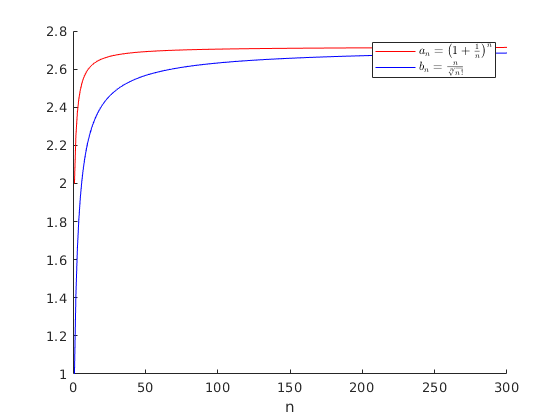

a_n = subs(f1, n, 1:300);
b_n = subs(f2, n, 1:300);
hold on
plot(a_n, 'r')
plot(b_n, 'b')
xlabel('n')
legend('$ a_n = \left(1+\frac{1}{n}\right)^n $', '$ b_n = \frac{n}{\sqrt[n]{n!}} $', 'Interpreter','latex')

由图可知 $a_n = \left(1+\frac{1}{n}\right)^n$ 收敛更快